# Introduction to Moving Frames   

This module will be a review of curves and their parametrizations, along with transformations on those curves in $\mathbb{R}^2$ and $\mathbb{R}^3$. This serves as both background material and motivation for studying the moving frames. The following modules describes some of the common frames:

[**Fernet Serret frame**](matlab:open('./Frenet_Serret_Frames.mlx'))**: **An interactive lesson on the Frenet Serret frame, which is the most commonly used and known moving frame method. Applications include generating trajectories using parameters like curvature and torsion in mechanical systems such as multi-link manipulators and unicycle models.

[**Natural Frenet frame**](matlab:open('./Natural_Frenet_Frames.mlx'))**: **An interactive lesson on the natural Frenet frame, where its similarities and differences with the Frenet-Serret frame are compared.

[**Affine frame**](matlab:open('./Affine_Frame.mlx'))**: **An interactive lesson on the equi-affine frame for 2-D as well as 3-D curves, defining concepts such as affine arc-length and affine curvature.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane. If the animations are causing slowdowns or not working correctly, uncheck the "animation" box for a simplified view of the module.

clear;
aFlag = true;

## Parametrized Curve

Consider an object moving in space. The position of that object can be described using the coordinates of that space as a vector $\mathbf{r}$. For example, in $\mathbb{R}^3$, 


$$\mathbf{r} = \pmatrix{x \cr y \cr z }$$


The history of the trajectory of that object can be described by a vector-valued function 


$$\mathbf{r}(t) =  \pmatrix{x(t) \cr y(t) \cr z(t)}$$


with each spatial coordinate depending explicitly on an independent parameter (often thought of as time). This vector-valued function is the *parametric equation* describing the trajectory of the object, and the path traced is a *parametric curve*. Play around with the variables ($a$, $b$) of a 2D curve given by the parametric equation 


$$\mathbf{r}(t) = \pmatrix{x(t)\cr y(t)} =  \pmatrix{\cos(at)\cr \sin(bt)}$$


and see what the resulting curve looks like.

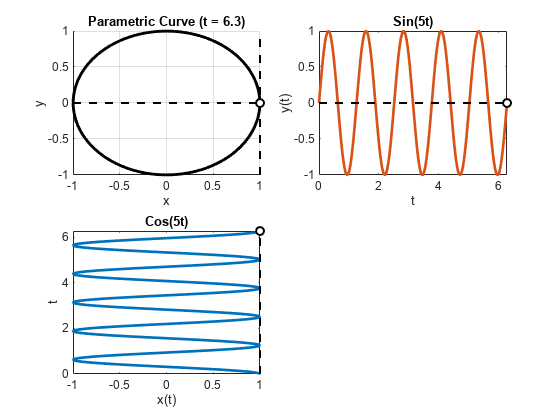

 a =5;
 b =5;
 
syms t;
% Calculating curve
tspan = linspace(0, 2*pi, 200);
x(t) = cos(a*t);
y(t) = sin(b*t);
numx = double((x(tspan)));
numy = double((y(tspan)));

% Plotting curve
figure
sub1 = subplot(2, 2, 1); % x-y plane
hold on;
cla(sub1);
plot(numx, numy, 'Color', 'k', 'LineWidth', 2)
axis tight
grid on

xlabel('x')
ylabel('y')

sub2 = subplot(2, 2, 3); % x(t)
cla(sub2);
axis equal
grid on
plot(numx, tspan, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel('t')
xlabel('x(t)')
title(['Cos(' num2str(a) 't)'])
hold on

sub3 = subplot(2, 2, 2); % y(t)
cla(sub3);
axis equal
grid on
plot(tspan, numy, 'SeriesIndex', 2, 'LineWidth', 2);
ylabel('y(t)')
xlabel('t')
title(['Sin(' num2str(b) 't)'])
hold on

% Drawing the reference lines
qlx1 = line(sub1, [x(1) x(1)], [-1 1], 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1.5);
qly1 = line(sub1, [-1 1], [y(1) y(1)], 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1.5);
qU = quiver(sub1, x(1), y(1), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qlx2 = line(sub2, [x(1) x(1)], [0 2*pi], 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1.5);
qx = quiver(sub2, tspan(1), numx(1), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qly2 = line(sub3, [0 2*pi], [y(1) y(1)], 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1.5);
qy = quiver(sub3, tspan(1), numy(1), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');

% Animate
if aFlag
    for i=1:length(tspan)
      time = round(tspan(i)*10)/10;
      title(sub1, ['Parametric Curve (t = ' num2str(time) ')'])

      qlx1.XData = [numx(i), numx(i)];
      qly1.YData = [numy(i), numy(i)];
      qlx2.XData = [numx(i), numx(i)];
      qly2.YData = [numy(i), numy(i)];

      qU.XData = numx(i);
      qU.YData = numy(i);
      qU.UData = 0;
      qU.VData = 0;

      qx.XData = numx(i);
      qx.YData = tspan(i);
      qx.UData = 0;
      qx.VData = 0;

      qy.XData = tspan(i);
      qy.YData = numy(i);
      qy.UData = 0;
      qy.VData = 0;
      
      drawnow
    end
end
hold off

If $\mathbf{r}(t)$ is differentiable, i.e. its components are differentiable, then we say that the curve is *regular* if and only if


$$\frac{d\mathbf{r}(t)}{dt} \neq 0$$


We can think of this condition intuitively as an object or particle never stopping or staying still in its trajectory.

### Changing the parameter

An interesting and important property of parametric curves is that a change in the parameter $t$ does not in fact change the curve. For example, if we substitute $t$ with $u(t) = 2t$, then for the curve shown above, $\mathbf{r}(u)$ looks like

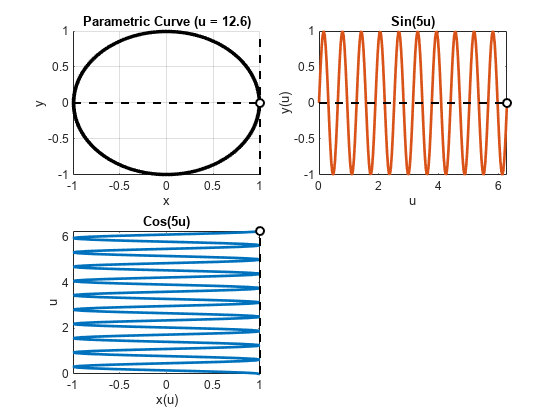

 
% Calculating curve
x(t) = cos(a*2*t);
y(t) = sin(b*2*t);
numx = double((x(tspan)));
numy = double((y(tspan)));

figure
sub1 = subplot(2, 2, 1); % x-y plane
hold on;
cla(sub1);
plot(numx, numy, 'Color', 'k', 'LineWidth', 2)
axis tight
grid on

xlabel('x')
ylabel('y')

sub2 = subplot(2, 2, 3); % x(t)
cla(sub2);
axis equal
grid on
plot(numx, tspan, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel('u')
xlabel('x(u)')
title(['Cos(' num2str(a) 'u)'])
hold on

sub3 = subplot(2, 2, 2); % y(t)
cla(sub3);
axis equal
grid on
plot(tspan, numy, 'SeriesIndex', 2, 'LineWidth', 2);
ylabel('y(u)')
xlabel('u')
title(['Sin(' num2str(b) 'u)'])
hold on

% Drawing reference lines
qlx1 = line(sub1, [x(1) x(1)], [-1 1], 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1.5);
qly1 = line(sub1, [-1 1], [y(1) y(1)], 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1.5);
qU = quiver(sub1, x(1), y(1), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qlx2 = line(sub2, [x(1) x(1)], [0 2*pi], 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1.5);
qx = quiver(sub2, tspan(1), numx(1), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qly2 = line(sub3, [0 2*pi], [y(1) y(1)], 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1.5);
qy = quiver(sub3, tspan(1), numy(1), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');

% Animate
if aFlag
    for i=1:length(tspan)
      time = round(tspan(i)*10)/10;
      title(sub1, ['Parametric Curve (u = ' num2str(2*time) ')'])

      qlx1.XData = [numx(i), numx(i)];
      qly1.YData = [numy(i), numy(i)];
      qlx2.XData = [numx(i), numx(i)];
      qly2.YData = [numy(i), numy(i)];

      qU.XData = numx(i);
      qU.YData = numy(i);
      qU.UData = 0;
      qU.VData = 0;

      qx.XData = numx(i);
      qx.YData = tspan(i);
      qx.UData = 0;
      qx.VData = 0;

      qy.XData = tspan(i);
      qy.YData = numy(i);
      qy.UData = 0;
      qy.VData = 0;
      
      drawnow
    end
end
hold off

We see that for a change in parameter, while the speed of the object changes, the path the object travels remain the same.

A very useful reparameterization of a curve is called the *arc-length parameterization*, which one can think of as substituting $t$ with an increasing function $s(t)$ such that $r(s)$ expresses the "length" of the curve $r$ at $s(t)$. This is explored in the Frenet-Serret frame module.

## Reference Frames

It is often necessary to know not only the position of an object, but its *orientation* as well. One method to track an object's orientation is by attaching a local *reference frame* to the object. 

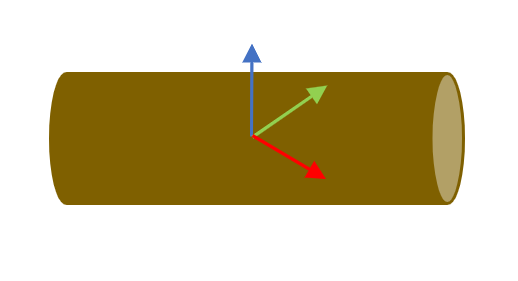

A reference frame is a set of linearly independent vectors centered at the attached object that provide coordinates with that center as the relative origin. If we define a vector in this local coordinate system as the "orientation" of the object, then any rotation of the object will rotate the reference frame, and thus this "orientation" vector in the same way.

 Frames are used extensively in tools such as MATLAB's Simscape Multibody™ to keep track of position and orientation of objects relative to each other. You can find more in the [Working with Frames page](https://www.mathworks.com/help/sm/ug/frames-and-frame-transforms.html).

### Moving Frames

If the object with the attached reference frame is in motion, then the reference frame becomes a *moving frame*, i.e. the origin of the local coordinate axis moves along the object's trajectory. This can be represented formally as a *transformation* on the frame. This is useful not only as a new way to describe curves, but to also *generate *trajectories using the intrinsic properties that arise natrually by describing them using frames. We will go more in depth on the different types of moving frames in the later modules.

## Group Transformations 

Let $X$ be the set of all points on a curve $\mathbf{r}(t)$, i.e.


$$X = \{x: x\in \mathbf{r}(t),\  t\in \mathbb{R}\}$$


Then we can represent a transformation on the curve as an action $g$ on the set $X$. Consider a curve $\mathbf{r}(t)$ in $\mathbb{R}^2$ that is rotated by an angle $\theta$.

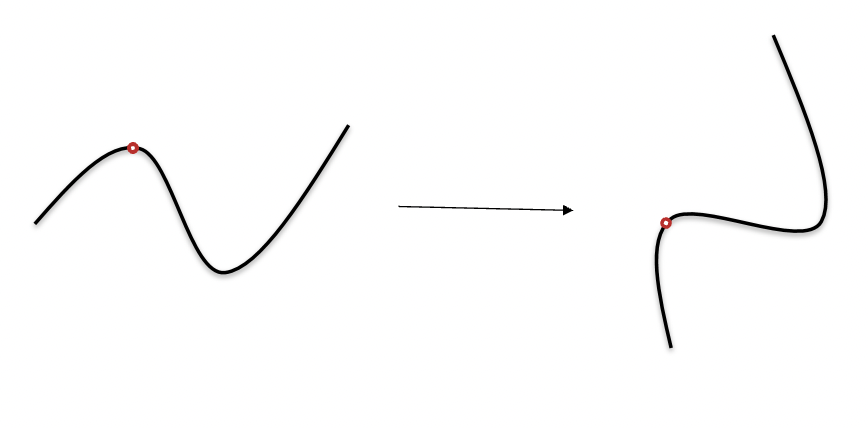

We can represent this rotation as every point on the curve $x\in \mathbf{r}(t)$ multiplied by the rotation matrix $g(\theta) =\pmatrix{\cos(\theta) & \sin(\theta) \cr -\sin(\theta) & \cos(\theta)}$. In other words the new curve $\tilde{\mathbf{r}}(t) = g(\theta)\cdot \mathbf{r}(t)$. $g$ is what is known as a *group action*, and the set of all group actions form a *group* which acts on a set $X$. 

For eample, the set of all rotations in $\mathbb{R}^2$ is known as the *Special Orthogonal group*, or $SO(2)$. It can be defined as a group of matrices $g$ such that 


$$SO(2) = {g =2\times 2 \ \text{matrix}: g^Tg = I, \det(g) = 1\}$$


Transformations that preserve the length between points of the curve, such as rotation or translation, are known as *Euclidean transformations*. The group of all rotations and translations in $\mathbb{R}^2$ is called the *Special Euclidean group*, or $SE(2)$ for short, and is defined by groups of matrices $g$ such that


$$SE(2) = \left\{g =\pmatrix{A & \mathbf{b} \cr 0 & 1} : A\in SO(2), \ \mathbf{b}\in \mathbb{R}^2 \right\}$$


We can clearly see how matrices in this group transform the original curve $\mathbf{r}(t)$ to a new curve $\tilde{\mathbf{r}}(t) = A\mathbf{r}(t) + \mathbf{b}$ through multiplying the group elements $g$ with the vector $\pmatrix{\mathbf{r}(t) \cr 1}$. 

Similarly, transformations that preserve area or volume are known as *Affine transformations,* and are described in $\mathbb{R}^2$by the *Special linear group*, or $SL(2)$. This group can likewise be defined as the matrix group


$$SL(2) = \{g = 2\times 2 \ \text{matrix}: \det(g) = 1 \}$$


The groups mentioned above are what are known as *Lie groups*, and what makes them interesting is that they have enough inherent structure for us to discuss *dynamics* on the groups, i.e. a trajectory of matrices $g(t)$. These kinds of dynamics on matrix groups can be observed in many physical systems, such as the motions of a unicyclist. 

The next module is an introduction to the [Fernet Serret frame](matlab:open('./Frenet_Serret_Frames.mlx')), the most commonly used and known moving frame method. 

## Problems

- Show that the curve $\mathbf{r}(t) = \pmatrix{e^t \cr e^{2t}-1}$ is a parabola.

- Show that for a rotation matrix $g(\theta)$ in $\mathbb{R}^2$, $g(\theta)\cdot g(-\theta) = I$ the identity matrix.

## Citations

Clelland, Jeanne N. *From Frenet to Cartan: the method of moving frames*. Vol. 178. American Mathematical Soc., 2017.

Millman, Richard S., and George D. Parker. *Elements of differential geometry*. Prentice Hall, 1977.

## Helper Functions

#### Auxiliary Functions

Extra utility functions used in the code

function [XLim, YLim, ZLim] = padax(ax, padding, zFlag)
    XLim = [ax.XLim(1)-padding ax.XLim(2)+padding];
    YLim = [ax.YLim(1)-padding ax.YLim(2)+padding];
    if zFlag
        ZLim = [ax.ZLim(1)-padding ax.ZLim(2)+padding];
    else
        ZLim = [];
    end
end